# Análise do erro

Seja G a FTMA e a relimentação unitária. e M = FTMF

s = tf('s');
K_a = 2;
G = (0.2*K_a)/((0.2*s + 1)*(0.5*s + 1));
M = feedback(G,1);
E = (1-M);

Qual é o tipo do sistema?

Ora, o *tipo* do sistema é a quantidade de pólos na origem. Não temos pólos na origem. Logo, o sistema é do tipo 0.

Qual é a ordem do sistema?

O sistema é de ordem 2, pois tem dois pólos.

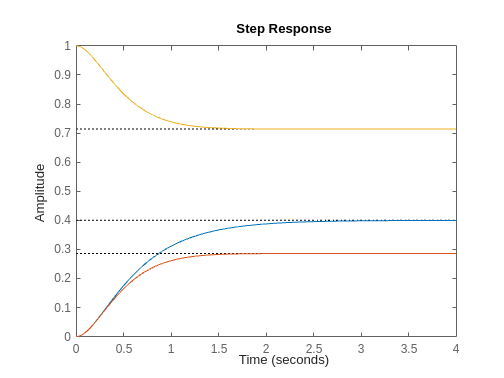

step(G,M,E);

O ganho do sistema é 0.2*K_a. O ganho, na notação padrão é 0.4. Logo, o erro de M para step é 1/(1+k) = 1/(1.4) = 0.71. Logo, a resposta final é 1 - 0.71 = 0.29 

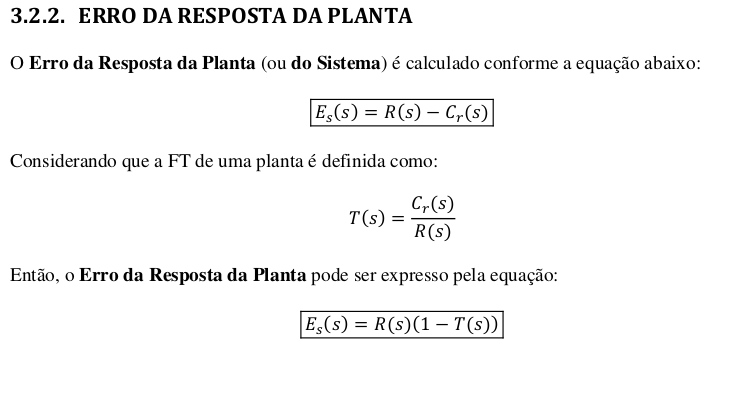

erro = 1/(1.4)

erro = 0.7143

As constantes de erros são constantes para facilitar o cálculo do erro. Em alguns casos, ela vai dar 0, causando o erro tender a infinito quando a resposta é uma rampa ou parábola.